## **How to use tfest() function**

First section, this section creates a sample transfer function $\frac{s+3}{2s^{2\;} +s+1}$. The data for tfest() function need input, output and sample time.

clc; clear;
warning off;
sys = tf([1,3],[2,1,1])

sys =
 
      s + 3
  -------------
  2 s^2 + s + 1
 
Continuous-time transfer function.



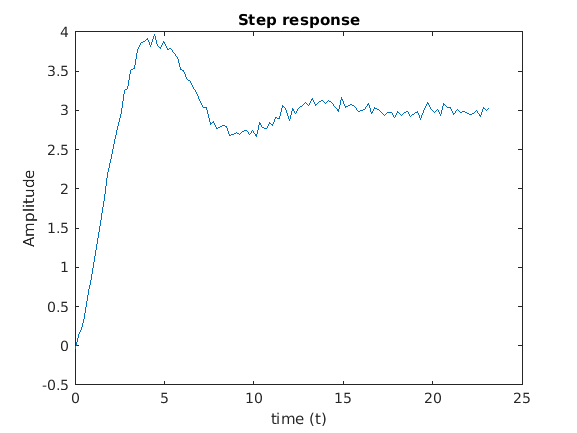


[A,t] = step(sys);
Ts = t(2) - t(1); % sample time %Warning for variable step size, it can not be used.
u = ones(length(A),1);
y = A+0.05*randn(length(A),1);
plot(t,y)
xlabel('time (t)'); ylabel('Amplitude'); title('Step response');

Second section, this section will generate iddata which is a properties of system. After that, we use tfest() to estimate the transfer function.

data = iddata(y,u,Ts);
sys = tfest(data,2,1)

sys =
 
  From input "u1" to output "y1":
     0.5328 s + 1.477
  -----------------------
  s^2 + 0.5016 s + 0.4936
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.09%                   
FPE: 0.002603, MSE: 0.002369                     


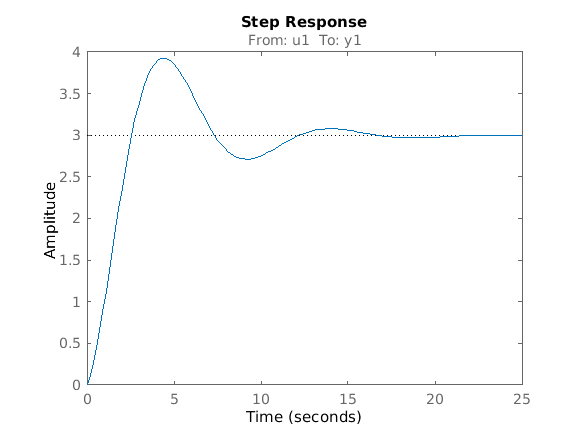

step(sys)

Final section, we will plot all result.

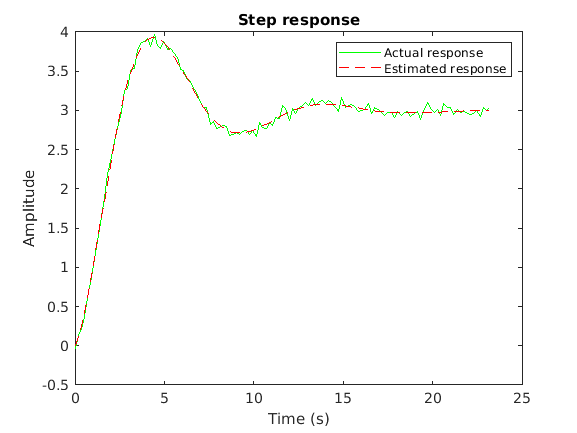

opt = stepDataOptions('StepAmplitude',u(end));
[y_fit,t_fit] = step(sys,opt,t(end));

figure
plot(t,y,'g',t_fit,y_fit,'--r');
xlabel('Time (s)'); ylabel('Amplitude'); title('Step response');
legend('Actual response', 'Estimated response')


$$G=\frac{\Omega \left(s\right)}{\frac{220}{s}}$$


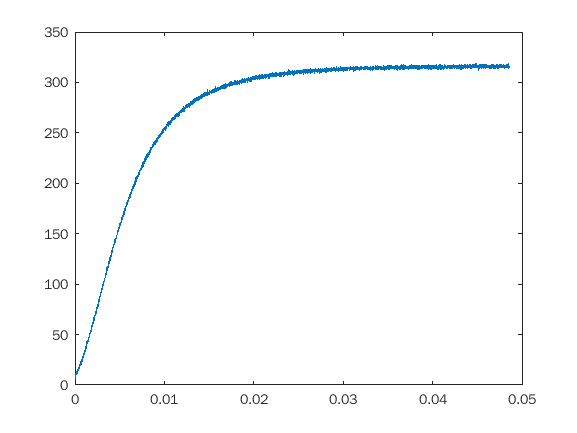

w = out.w;
u = out.Input;
t = out.tout;


%% Fitting curve
figure
plot(t(142:end)-t(142),w(142:end))


td = t(142); %Time delay is read from graph
stepcurve = 'a*(1-exp(-x/b))'; % a = DCgain * 220, b = time constant
f1 = fit(t(142:end)-t(142),w(142:end),stepcurve,'Start', [300 0.009]);

K = f1.a/220

K = 1.4467

tau = f1.b

tau = 0.0068

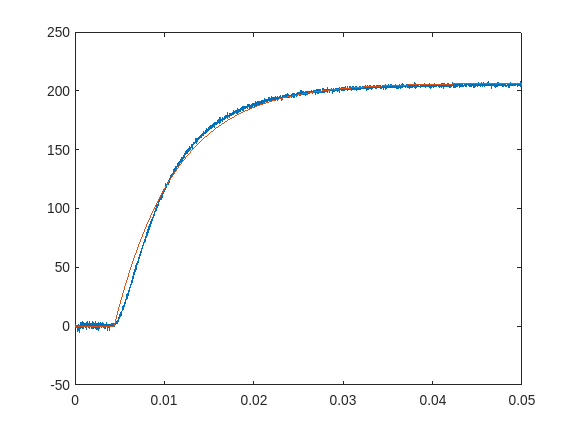

%% transfer function
G = tf(K,[tau 1], 'InputDelay', td);

yhat =step(G,t)*220;
figure
plot(t,w); hold on;
plot(t,yhat);